## Problem 2

- **Implementing K-Means Clustering**

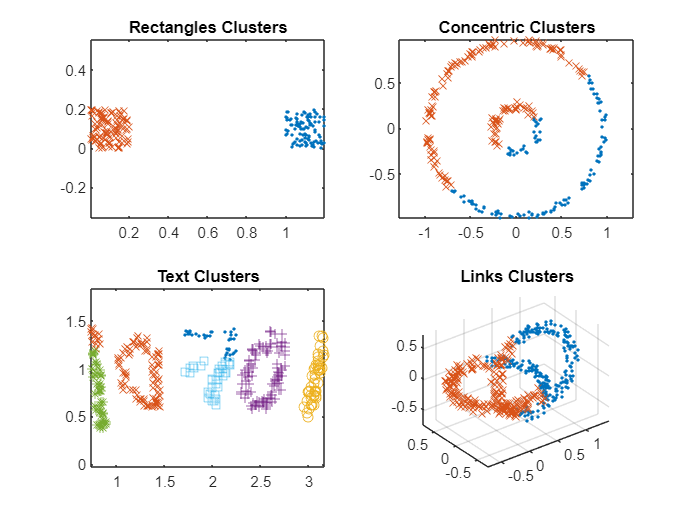

% Note - I removed the new figure initialization [figure;] in plotClusters.m in order
% to use subplots in my code.

% Load the datasets
load("rectangles.mat"); % loads X2
load("concentric.mat"); % loads X1
load("text.mat");       % loads X4
load("links.mat");      % loads X3

% Perform k-means clustering on each dataset
rect_clusterIdx = kmeans(X2, 2);
conc_clusterIdx = kmeans(X1, 2);
text_clusterIdx = kmeans(X4, 6);
links_clusterIdx = kmeans(X3, 2);

% Create a 2x2 grid of subplots
figure;

% Plot and title for rectangles
subplot(2,2,1);
plotClusters(X2, rect_clusterIdx);
title('Rectangles Clusters');
% Plot and title for concentric
subplot(2,2,2);
plotClusters(X1, conc_clusterIdx);
title('Concentric Clusters');
% Plot and title for text
subplot(2,2,3);
plotClusters(X4, text_clusterIdx);
title('Text Clusters');
% Plot and title for links
subplot(2,2,4);
plotClusters(X3, links_clusterIdx);
title('Links Clusters');

% Adjust the layout
sgtitle;

**2. Implement affinity matrix spectral clustering**

ans = 'Plots for sigma: 2.500000e-02'

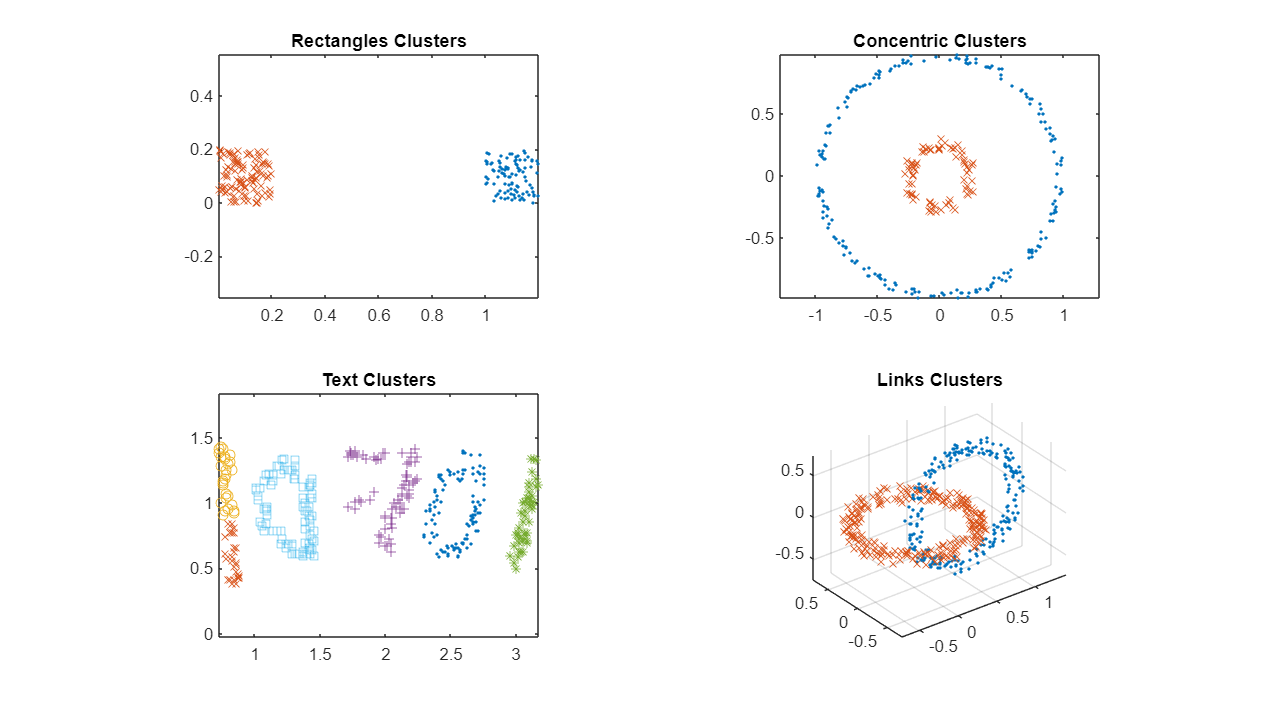

ans = 'Plots for sigma: 5.000000e-02'

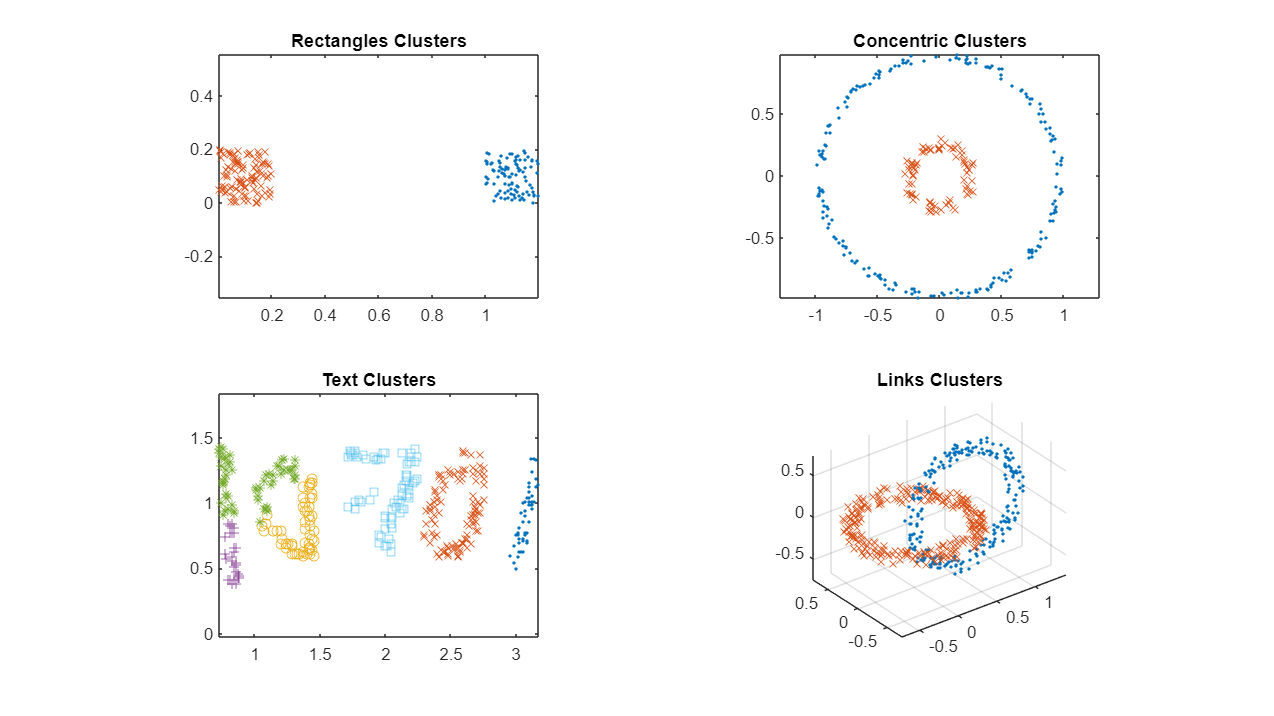

ans = 'Plots for sigma: 2.000000e-01'

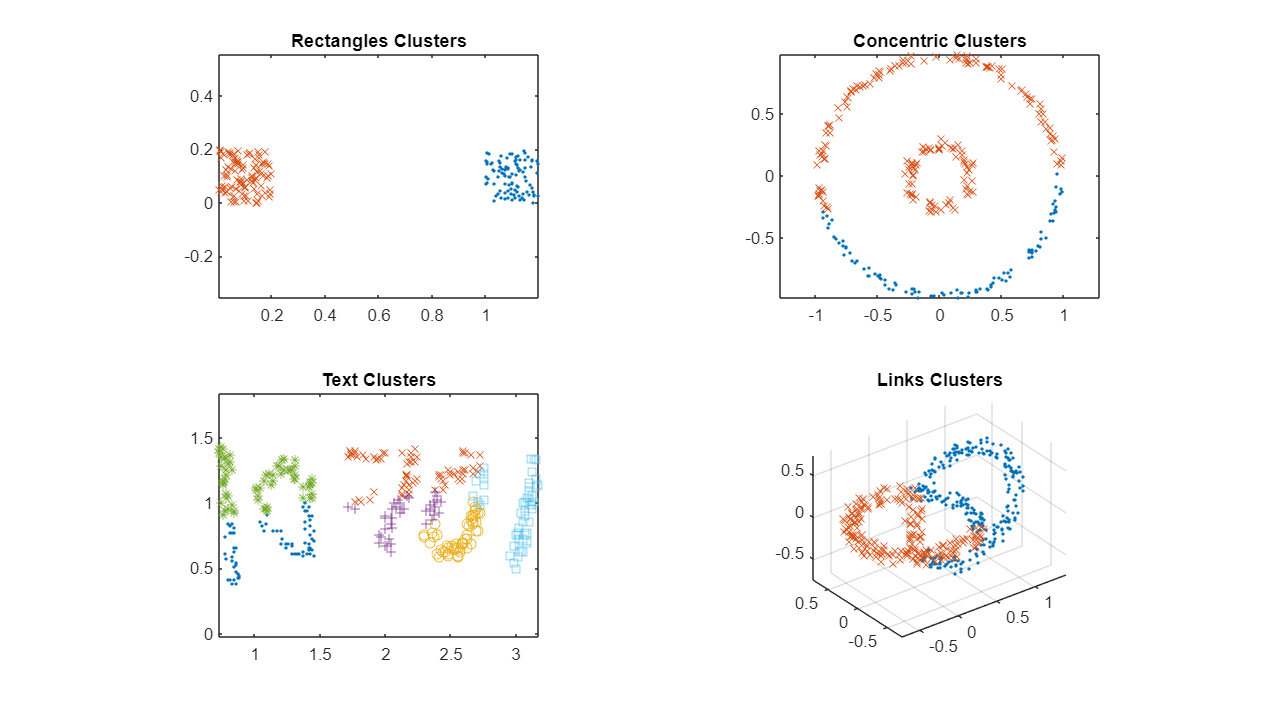

ans = 'Plots for sigma: 5.000000e-01'

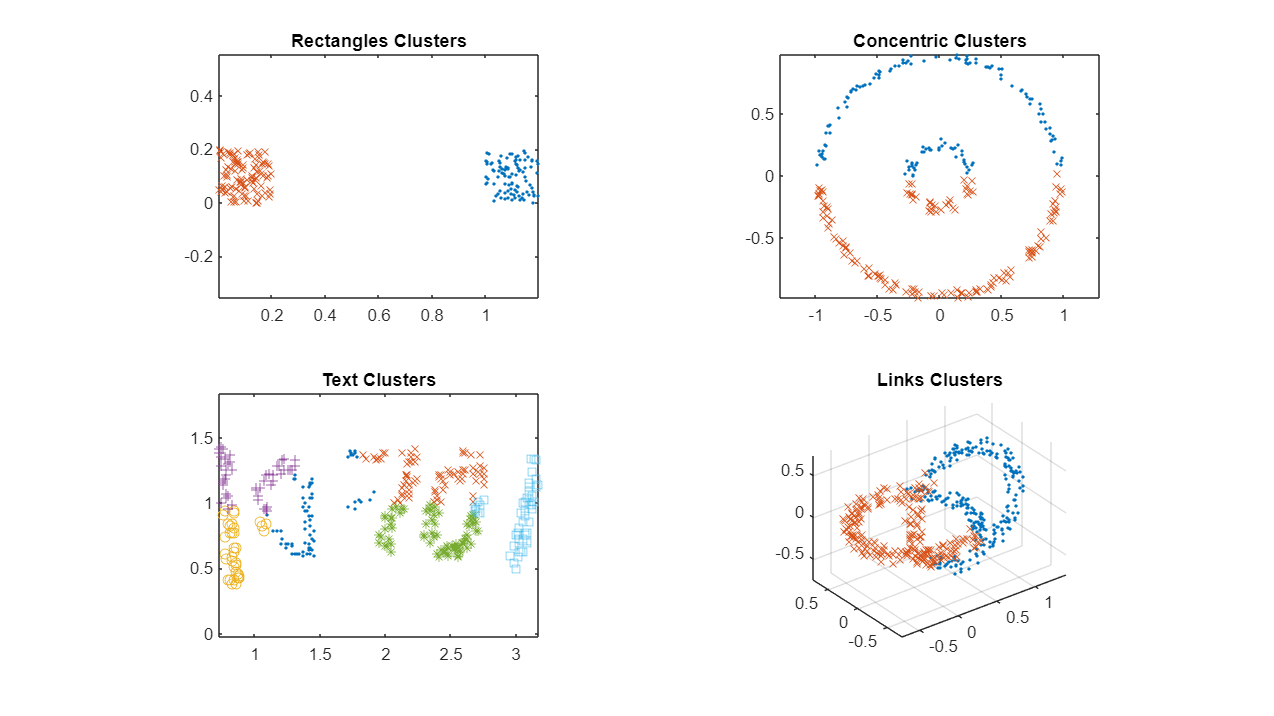

sigma = [.025, .05, .2, .5];
for i = sigma
    [rect_clusterIdx, ~] = affinity_matrix_clustering(X2, 2, i);
    [conc_clusterIdx, ~] = affinity_matrix_clustering(X1, 2, i);
    [text_clusterIdx, ~] = affinity_matrix_clustering(X4, 6, i);
    [links_clusterIdx, ~] = affinity_matrix_clustering(X3, 2, i);
    
    sprintf('Plots for sigma: %d', i)
    
    % Create a new figure window
    figure;

    % First subplot for rectangles
    subplot(2,2,1)
    plotClusters(X2, rect_clusterIdx);
    title('Rectangles Clusters');
    
    % Second subplot for concentric
    subplot(2,2,2)
    plotClusters(X1, conc_clusterIdx);
    title('Concentric Clusters');
    
    % Third subplot for text
    subplot(2,2,3)
    plotClusters(X4, text_clusterIdx);
    title('Text Clusters');
    
    % Fourth subplot for links
    subplot(2,2,4)
    plotClusters(X3, links_clusterIdx);
    title('Links Clusters');
    
    % Optionally, adjust the layout if the plots are overlapping
    set(gcf, 'Position', get(0, 'Screensize')); % For fullscreen, if needed
end

**3. Plot first 10 Eigenvalues for rectangles.mat and text.mat**

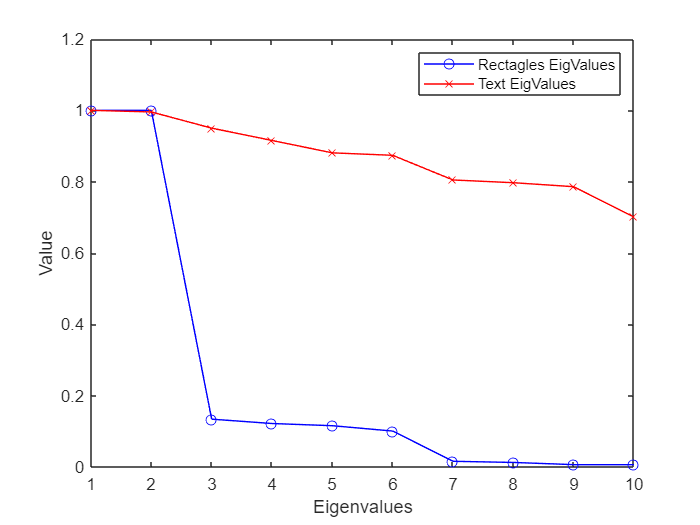

[~, rect_Eigs] = affinity_matrix_clustering(X2, 10, .05);
[~, text_Eigs] = affinity_matrix_clustering(X4, 10, .05);

figure;
plot(1:10, diag(rect_Eigs), 'b-o');
hold on;
plot(1:10, diag(text_Eigs), 'r-x');
xlabel("Eigenvalues")
ylabel("Value")
legend('Rectagles EigValues', 'Text EigValues');

**ANS -**

"Rectangles EigValues" shows a significant drop between the first and second eigenvalue, suggesting a strong principal component. This steep decline indicates that the first eigenvalue captures a substantial amount of the variance within the "Rectangles" dataset.

"Text EigValues" decreases more gradually, indicating that the variance in the "Text" dataset is more evenly spread across the components. There isn't a single eigenvalue that dominates, which could suggest a more complex underlying structure.

**4. How do k-means and spectral clustering compare?**

K-means clustering is great for simple, round clusters of similar size but falls short with intricate shapes or clusters of varying sizes. It separates rectangular clusters well but doesn't quite capture the layered pattern of concentric circles due to its reliance on straight-line distances.

Spectral clustering, on the other hand, excels in these complex scenarios. By considering how all data points relate to one another, it effectively reveals the circular layers and the subtle groupings in the text and link data.

In essence, while K-means imposes a straightforward but sometimes overly simplistic structure, spectral clustering adapts to the data's natural patterns, making it a better choice for intricate cluster shapes.